# Cargar la información con prueba de parámetros 

### Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok


anios = 2000:2022;

Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
        
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

>>> Cargando área de estudio


Pixeles en total del área de estudio

total_pixeles = sum(area_estudio,"all");

### Consulta de la información

Consultar las imágenes del año 2022

Con la función FIND de Matlab se realizan las consultas de la tabla

tmp = find(  info_hdf.anio >= 2000 & info_hdf.anio <=2022);
info_consulta = info_hdf(tmp,:);
[filas,~] = size(info_consulta);
disp("Total de imágenes: "+filas);

Total de imágenes: 519


### Recuperar la información y crear las matrices de 3 dimensiones

Declaración de los arreglos que se ocuparan para obtener la información

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);
% arreglo 3d para la calidad del pixel
arr_ndvi_qa = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);
arr_ndvi_nan = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo 3d de ndvi por día con filtro Saviztky
arr_ndvi_sgf = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo 3d de ndvi por día con filtro Lanczos
arr_ndvi_lf = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);


Recuperar toda la información y marcar los dias como baja disponibilidad

bp=waitbar(0,'Obteniendo información de archivos MODIS'); 
for i=1:filas
    [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(area_estudio==false)=NaN;
    disponibilidad(area_estudio==false)=NaN;

    %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_qa(:,:,i) = disponibilidad;

    arr_ndvi_lf(:,:,i) = ndvi;
    arr_ndvi_sgf(:,:,i) = ndvi;

    
    %barra de progreso
    waitbar(i/filas,bp,sprintf('Obteniendo información de archivos MODIS (%3.0f%%) ',(i/filas*100)));
end
close(bp); 


Mostrar el promedio de NDVI de toda la serie

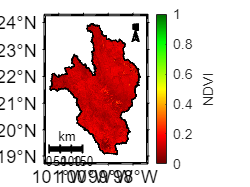

ndvi_prom = m_mean_3dpp(arr_ndvi);
ndvi_prom(area_estudio==false)=nan;

m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"",[0 1],ndvi_colormap,"NDVI");
m_dibujar_kml(dir_data,"RH26",1,'k',"")

exportgraphics(gca,"img/promedio_ndvi.png",'Resolution',300) 

## Filtrar con Lanczos y Savitzky-Golay 

generar ndvi filtrado

%Mejores parametros para el filtro Lanczos
dT = 23;
cf= 1/46;

% Mejores parametros para Savitzky-Golay
order = 3;
framelen = 7;

bp=waitbar(0,'Generando series de tiempo con filtros'); 
for i=1:ndvi_tam(1)
     for j=1:ndvi_tam(2)
         if area_estudio(i,j) == true

             S  = reshape( arr_ndvi(i,j,:),[],1);
             SNan =  reshape( arr_ndvi_nan(i,j,:),[],1);

             arr_ndvi_nan(i,j,:) = m_rm_pixel_baja_calidad(arr_ndvi(i,j,:),arr_ndvi_qa(i,j,:));

             [xs,~,~,~,~] = lanczosfilter(S,dT,cf,[],'low');  
             arr_ndvi_lf(i,j,:) = xs;

             arr_ndvi_sgf(i,j,:) = sgolayfilt(S,order,framelen);

         end

     end
     waitbar(i/filas,bp,sprintf('Generando series de tiempo con filtros (%3.0f%%) ',(i/filas*100)));
end
close (bp);

Mostrar el promedio de NDVI FILTRO LANCZOS de toda la serie

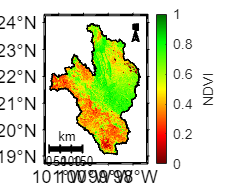

ndvi_prom = m_mean_3dpp(arr_ndvi_lf);
ndvi_prom(area_estudio==false)=nan;

m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"",[0 1],ndvi_colormap,"NDVI");
m_dibujar_kml(dir_data,"RH26",1,'k',"")

exportgraphics(gca,"img/promedio_ndvi_lf.png",'Resolution',300) 

Mostrar el promedio de NDVI FILTRO SAVITZKY de toda la serie

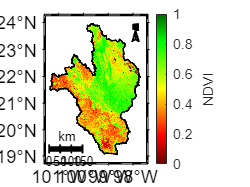

ndvi_prom = m_mean_3dpp(arr_ndvi_sgf);
ndvi_prom(area_estudio==false)=nan;

m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"",[0 1],ndvi_colormap,"NDVI");
m_dibujar_kml(dir_data,"RH26",1,'k',"")

exportgraphics(gca,"img/promedio_ndvi_sgf.png",'Resolution',300) 